# **PATCH ANTENNA DESIGN**

clear; clc; 

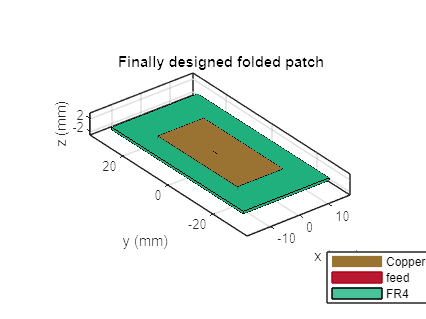

clear; clc; 
f = 2.1e9; % resonant frequency 
p = design(pifa, f); 
% creating standard pifa with shorting width equalling W 
% This makes it have the same structure of a (lambda/4) 
% folded patch antenna

% NON optimized patch length and width
% They have been evaluated by using Wolfram Mathematica
% Right there, the classic formulas from Balanis have been executed

% W = 0.0419;
% L = 0.0171;

% OPTIMIZED patch length and width
% This values come out after the mesh refinement process 
% and impedance matching 

W= 0.0351; 
L = 0.0158; 

h = 0.0008; % substrate thickness and patch height
lambda0 = physconst('Lightspeed')/f; % free space wavelength at given frequency
k0=2*pi/lambda0; % propagation constant

% patch parameters setting
p.Length = L;
p.Width = W;
p.Height = h;
p.Substrate.Name = 'FR4';
p.Substrate.EpsilonR = 4.8;
p.Substrate.LossTangent = 0.026;

% Substrate thickness h=8e-4 has been used by following the Antenna Toolbox
% rationale, which doesn't give any precise guideline in the mesh refinement process
% by means of an accuracy indication in the case of 
% h between (lambda/50, lambda/10). h would have belonged to this range
% in case of h={1.0e-3, 1.6e-3}. Out of this range, for h < lambda/50, the mesh is
% regarded as a thin one, and the tool suggests to set 'auto' mesh level to aquire 
% best accuracy. In the case of h comparable to lambda/10, the tool requires at least
% a max mesh edge length comparable to the lambda/10 value. 
% That's why we selected h = 8e-4;
p.Substrate.Thickness = h;
p.ShortPinWidth = W; 
% since no folded patch antenna structure is directly available 
% in the tool, by selecting (short circuit width) wsc = W, 
% the pifa structure equals the design of a folded patch antenna
p.PatchCenterOffset = [0 0];
Rr = (120*lambda0/W)*(1-(1/24)*(k0*h)^2)^(-1);
Rin = 50;

% FEED POINT - coming out of an impedance matching process
lfeed= 0.0067; % optimized value 
wfeed = 0.0010; % optimized value

% wfeed = 0;
% lfeed = (L/pi)*acos(sqrt(Rin/Rr)); % standard computation 

p.FeedOffset = [lfeed-L/2 wfeed];

% OPTIMIZED ground lenght and width
% we started with [gpL, gpW] = [0.08, 0.08]
gpL = 0.0296;
gpW = 0.058; 
p.GroundPlaneLength = gpL;
p.GroundPlaneWidth = gpW;

% selection of a realistic conductor
% Copper is used in our University lab
p.Conductor.Name = 'Copper';
p.Conductor.Conductivity = 5.96*1e7;
p.Conductor.Thickness = 3.556e-05;


% show the 
figure;
show(p);
title('Finally designed folded patch');

## BEAMWIDTH

figure;
mesh(p,'MaxEdgeLength',0.0035);
title('Mesh');
figure;
beamwidth(p,f,0,0:1:360);
title('Beamwidth - H-cut');
figure;
beamwidth(p,f,0:1:360,0);
title('Beamwidth - E-cut');

## MESH LEVEL REFINEMENT PROCESS

v = 0.0026:0.000025:0.0039;
smin = zeros(1,length(v));
freqRange = 2e9:0.0025e9:2.2e9;

tic
parfor i=1:length(v)
mesh(p,'MaxEdgeLength',v(i));
drawnow
s = sparameters(p,freqRange);
svar = 20*log10(abs(s.Parameters));
smin(1,i) = min(min(min(svar)));
disp('Step: ');
disp(length(v)+1-i);
end 
figure();
plot(v,smin);
toc

## IMPEDANCE MATCHING

lfeed = 0.0060:0.0001:0.008;
wfeed = -0.005:0.0001:0.005;
figure();
mesh(p,'MaxEdgeLength',0.0035);
for i=1:length(wfeed)
p.FeedOffset = [lfeed-L/2 wfeed(i)];
% p.FeedOffset = [lfeed(i)-L/2 0];
freqRange = 2e9:0.002e9:2.2e9;
figure();
% sparameter
impedance(p, f);
title(string(wfeed(i)));
disp('Step: ');
disp(length(wfeed)-i);
end
disp('Done!');

## IMPEDANCE DIAGRAM

freqRange = 2e9:0.002e9:2.2e9;

% sparameter
figure();
mesh(p,'MaxEdgeLength',0.0035);
figure();
impedance(p, freqRange); 
title('Impedance matched')

## GAIN PATTERNS - dBi diagrams

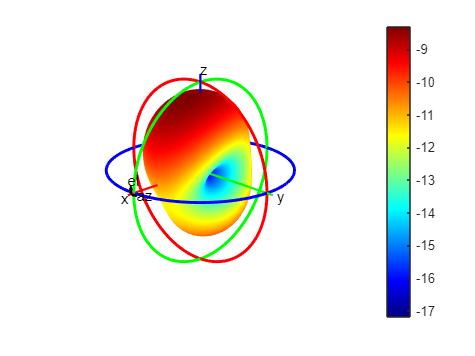

% diag structure is the same matricx as G0, except for subtracting
% - 2.15 dB to get from dBi scale to dB

[diag,AZ,EL] = pattern(p, f, 'Type', 'Gain');

ang1 = AZ';
ang2 = 90-(EL);
matr = diag';
th = linspace(0,360,37);
figure;
patternCustom(matr,ang2,ang1);

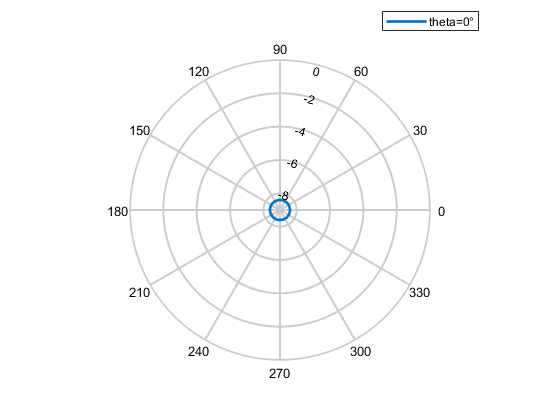

figure;
patternCustom(matr,ang2,ang1,'Slice','theta','SliceValue',0);

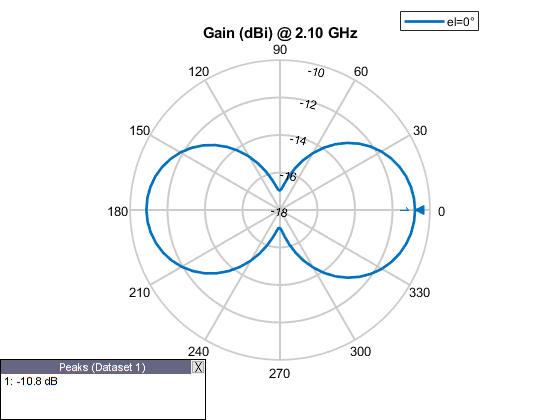

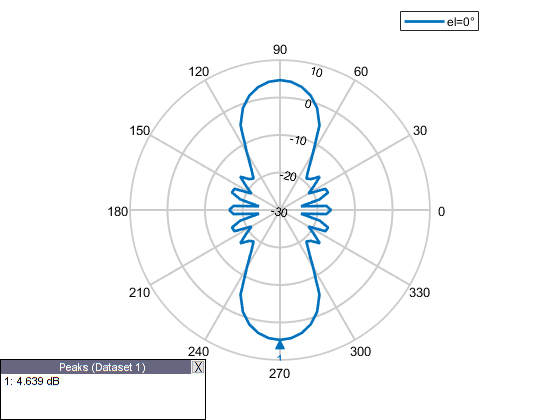

plotFrequency = 2.1e9;

pat_p = patternAzimuth(p, plotFrequency, 0, 'Azimuth', linspace(-180,180,73)); 
figure;
patternAzimuth(p, plotFrequency, 0, 'Azimuth', linspace(-180,180,73))

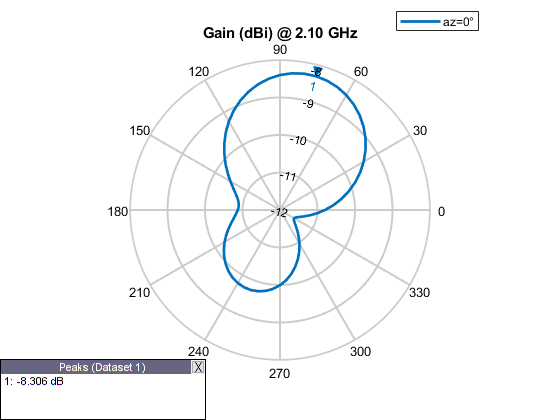

figure;
patternElevation(p, plotFrequency, 0, 'Elevation', 0:5:360)

## GAIN PATTERN - matrix in dB

% By running this, you get results in a different scale
% G0 = pattern(p, 2.1e9, 'Normalize',true,'Type', 'Gain');
G0 = pattern(p, 2.1e9,'Type', 'Gain');
G0 = G0+9;

newax = rotz(90);
pat_p = rotpat(G0,linspace(-180,180,73),linspace(-90,90,37),newax);
thet = linspace(-90,90,73);



figure;
patternCustom(pat_p, 90-theta, phi,'CoordinateSystem','polar',...
    'Slice','theta','SliceValue',0);

Error using patternCustom
The value of 'MagE' is invalid. Expected input to be of size 73x37, but it is of size 37x73.

Error in patternCustom (line 102)
parse(parseobj, MagE, theta, phi, varargin{:});

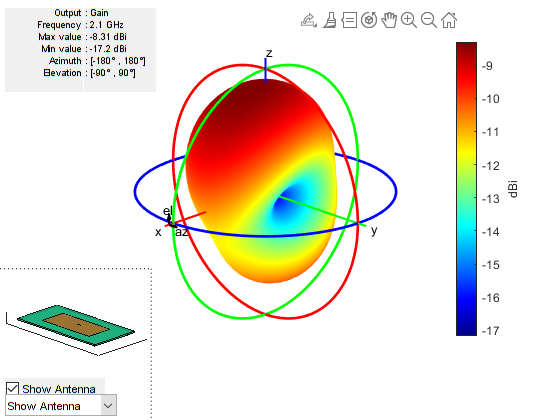


figure;
pattern(p, 2.1e9,'Type', 'Gain');

## GAIN PATTERNS - different polarization

% consider using vertical polarization for the matrix computation
pattern(p, f, 'Type', 'Gain', 'Polarization', 'v');
figure;
pattern(p, f, 'Type', 'Gain', 'Polarization', 'h');
figure;

## OTHER PLOTS

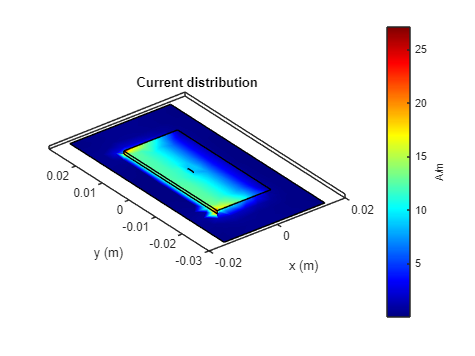

% CURRENT 
figure;
current(p, 2.1e9)

## DIRECTIVITY

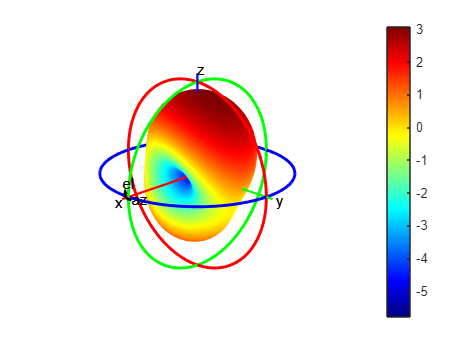


pat_dir = pattern(p,f,'Type','directivity');

az = linspace(-180,180,73);
el = linspace(-90,90,37);
newax = rotz(90);
pat2= rotpat(pat_dir,az,el,newax);

figure;
patternCustom(pat2',90-el,az);
% patternCustom(pat2',90-el,az);

## GAMMA PLOT

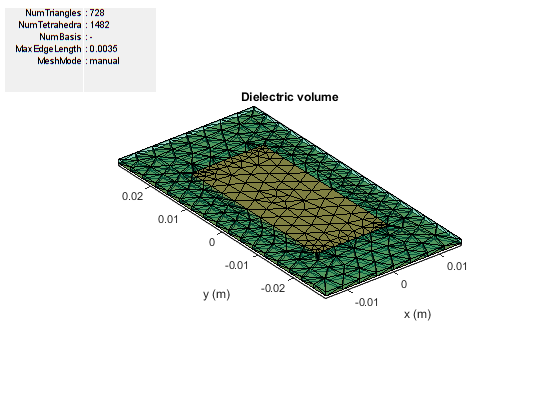


% Define plot frequency 
plotFrequency = 2.1*1e9;
% Define frequency range 
freqRange = 2.0e9:0.0025e9:2.2e9;
figure;
mesh(p,'MaxEdgeLength',0.0035);

% sparameter
figure;
s = sparameters(p, freqRange); 
rfplot(s)

## ANOTHER MESH REFINEMENT PROCESS

plotFrequency = 2.1*1e9;
% Define frequency range 
v = 0.0025:0.0001:0.009;
smin = zeros(1,length(v));
freqRange = 2.0e9:0.0025e9:2.2e9;

tic
parfor i=1:length(v)
mesh(p,'MaxEdgeLength',v(i));
% sparameter
figure;
s = sparameters(p, freqRange); 
svar = 20*log10(abs(s.Parameters));
smin(1,i) = min(min(min(svar)));
disp('Step: ');
disp(length(v)-i);
end
figure();
plot(v,smin);
toc
% rfplot(s)

## FINDING OPTIMAL L,W by using contour plot

clear L W l 
L = 0.0156:0.0001:0.0163;
W = 0.034:0.0001:0.049;

Rr = zeros(length(W),1);
l = zeros(length(L),length(W));
Gamma = zeros(length(L),length(W));
gpL = 0.029:0.0001:0.0297;
gpW = 0.044:0.0001:0.059; 

tic
disp('Total steps: ');
disp(length(L)*length(W));
for i=1:length(L)
    for j=1:length(W)
Rr(j,1) = (120*lambda0/W(j))*(1-(1/24)*(k0*h)^2)^(-1);
Rin = 50;
l(i,j) = (L(i)/pi)*acos(sqrt(Rin/Rr(j))); %% now it's from the shortC
    end
end

for i=1:length(L)
    for j=1:length(W)
    p.Length = L(i);
p.Width = W(j);
p.PatchCenterOffset = [0 0];
p.FeedOffset = [l(i,j)-L(i)/2 0];
p.ShortPinWidth = W(j);
p.GroundPlaneLength = gpL(i);
p.GroundPlaneWidth = gpW(j);
mesh(p, 'MaxEdgeLength',0.0035);
Spar = sparameters(p,f);
Gamma(i,j) = abs(Spar.Parameters);
disp('Step L: ');
disp(i);
disp('Step W: ');
disp(j);
    end
end
toc

% CONTOURS 

figure();
contourf(W,L,Gamma);
colorbar;
figure();
contourf(W,L,20*log10(Gamma));
colorbar;

# **TCHEBYSHEV ARRAY**

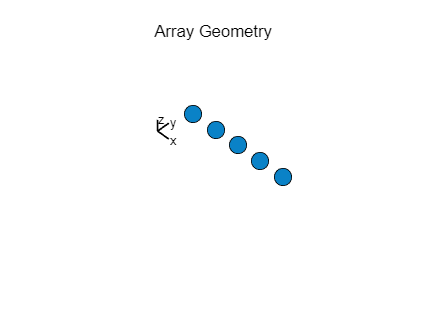

tcheB = phased.ULA('NumElements',5,...
'ArrayAxis','x');
tcheB.ElementSpacing = 0.0939;
sll = 41.58;
chebn = chebwin(5, sll);
tcheB.Taper = chebn;

Cheb_Currents = 41.2*chebwin(5,sll);

% Assign Frequencies and Propagation Speed
tcheB.Element = dotchy;

% short_dipole = phased.ShortDipoleAntennaElement; 
% figure;
% show(short_dipole);
% title('Phased short dipole');

% Array.Taper(1) = chebn(1);
% Array.Taper(2) = 0;
% Array.Taper(3) = 0;
% Array.Taper(4) = 0;
% Array.Taper(5) = 0;

Frequency = 2.1e9;
PropagationSpeed = 300000000;

% Assign Steering Angles
SteeringAngles = [0;90];
% Assign Phase shift quantization bits
PhaseShiftBits = 0;

% Create Figure

% Plot Array Geometry
figure;
viewArray(tcheB,'ShowNormal',false,...
  'ShowTaper',false,'ShowIndex','None',...
  'ShowLocalCoordinates',true,'ShowAnnotation',false,...
  'Orientation',[0;0;0]);

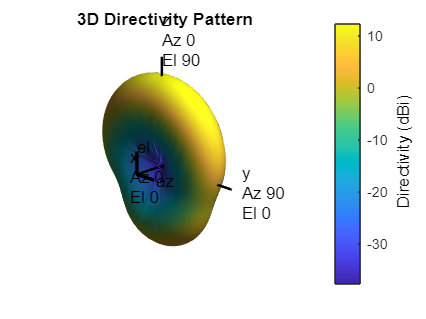



figure;
pattern(tcheB,2.1e9,'Type','directivity')

## FIRST PATTERN

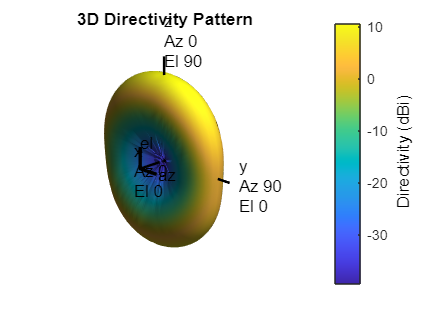

% Find the weights

Freq3D = 2.1e9; 

w = zeros(getNumElements(tcheB), length(Frequency));
SteerVector = phased.SteeringVector('SensorArray', tcheB,...
 'PropagationSpeed', PropagationSpeed, 'NumPhaseShifterBits', PhaseShiftBits(1));
for idx = 1:length(Frequency)
    w(:, idx) = step(SteerVector, Frequency(idx), SteeringAngles(:, idx));
end

% Plot 3d graph
format = 'polar';
figure;
pattern(tcheB, Freq3D , 'PropagationSpeed', PropagationSpeed,...
 'Type','directivity' , 'CoordinateSystem', format,'weights', w(:,1),...
  'ShowArray',false,'ShowLocalCoordinates',true,...
  'ShowColorbar',true,'Orientation',[0;0;0]);

Gt_patches = pattern(tcheB, Freq3D , 'PropagationSpeed', PropagationSpeed,...
 'Type','directivity', 'CoordinateSystem', format,'weights', w(:,1),...
  'ShowArray',false,'ShowLocalCoordinates',true,...
  'ShowColorbar',true,'Orientation',[0;0;0]);
Gt_dipoli = Gt_dipoli - 2.15; 

Unrecognized function or variable 'Gt_dipoli'.

## GAIN PATTERN

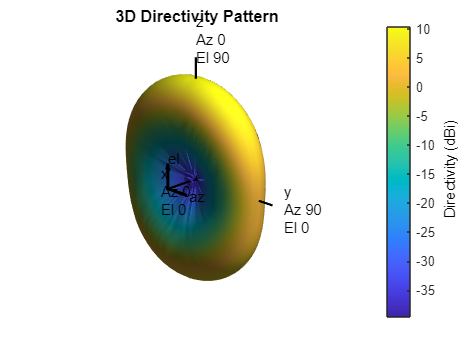

gain = phased.ArrayGain('SensorArray',tcheB);
% ang_phi = linspace(-180,180,360);
% ang_theta = linspace(-90,90,360);

ang_phi = linspace(-180,180,73);
ang_theta = linspace(-90,90,37);
g = zeros(length(ang_phi),length(ang_theta));
for i=1:73
    for j=1:37
g(i,j) = gain(2.1e9,[ang_phi(i);ang_theta(j)]);
% g = gain(fc,[30;20])
    end
end
g_pat = pattern(tcheB,2.1e9,ang_phi,ang_theta);
pattern(tcheB,2.1e9,ang_phi,ang_theta);

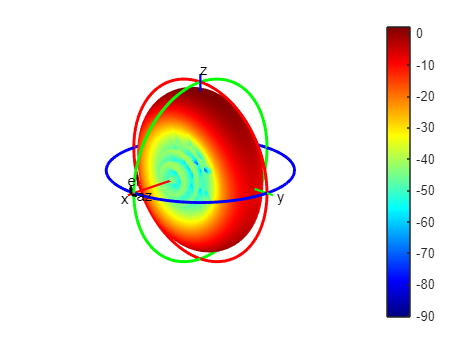

figure;
patternCustom(g,90-ang_theta,ang_phi);

figure;
g_pat = pattern(tcheB,2.1e9,ang_phi,ang_theta);
pattern(tcheB,2.1e9,ang_phi,ang_theta);

GGGF = abs(g).^2/(Cheb_Currents(3)^2+Cheb_Currents(2)^2+Cheb_Currents(3)^2);
Gpartial = g_pat./GGGF;

Arrays have incompatible sizes for this operation.

Related documentation

object_g = g_pat./g';

# **ARRAY FACTOR**

SubObject = design(helix, 2100*1e6);
arrayhelix = design(linearArray('Element', SubObject), 2100*1e6, SubObject);
arrayhelix.NumElements = 5;
arrayhelix.ElementSpacing = 0.0939;
% arrayhelix.AmplitudeTaper = [chebn(1), chebn(2), chebn(3), chebn(4), chebn(5)];


## PATTERN MULTIPLICATION PRINCIPLE

arrayhelix.AmplitudeTaper = [chebwin(1), chebwin(2), chebwin(3), chebwin(4), chebwin(5)];

Error using horzcat
Dimensions of arrays being concatenated are not consistent.


[PAT,AZ,EL] = arrayFactor(arrayhelix, 2.1e9);
phi = AZ';
theta = 90-(EL);
MagE = PAT';
th = linspace(0,360,37);
figure;
patternCustom(PAT',theta,phi);
figure; 
arrayFactor(arrayhelix, 2.1e9);
Factor = arrayFactor(arrayhelix, 2.1e9);
angoli = linspace(0,360,73);

Gf = (PAT.^2)/(2*Cheb_Currents(1)^2+2*Cheb_Currents(2)^2+Cheb_Currents(3));

% C0 = Cheb_Currents(3);
% C1 = Cheb_Currents(2);
% C2 = Cheb_Currents(1);
% Gf = (Factor.^2)/(2*C2^2+2*C1^2+C2^2);

 etaT = 0.79; 
% GTOT = etaT*dip_fact.*Factor;
figure;
patternCustom(Factor',theta,phi);

Unrecognized function or variable 'Factor'.

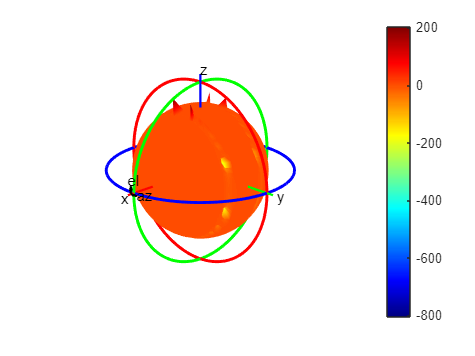

 etaT = 0.79;
 Gain_FACTOR = Gt_patches./(etaT*pat2); 
 Gain_ELEMENT = Gt_patches./(etaT*Factor.*Factor);
figure;
patternCustom(Gain_ELEMENT',90-el,az);


C_0 = Cheb_Currents(3);
C_1 = Cheb_Currents(2);
C_2 = Cheb_Currents(1);

% Array_Factor = abs(sqrt(Gain_FACTOR*(2*chebn(1)^2+2*chebn(2)^2+chebn(3)^2)));
% figure;
% patternCustom(Array_Factor',90-el,az);

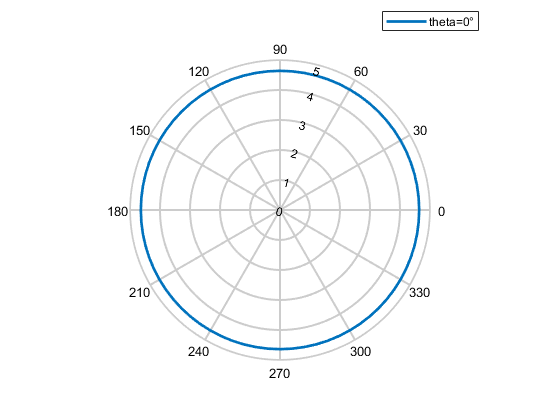

Factor_slice = patternCustom(Factor',theta,phi,'Slice','theta','SliceValue',0);

figure;
patternCustom(Factor',theta,phi,'Slice','theta','SliceValue',0);

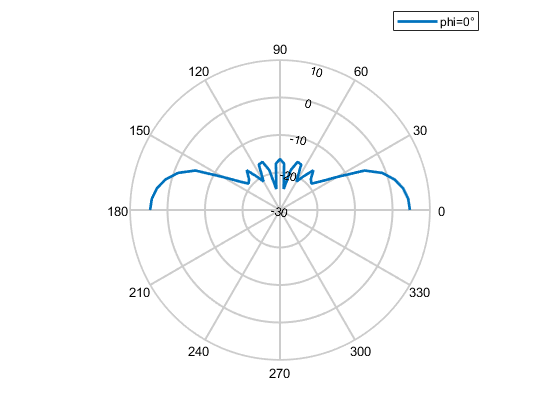

figure;
patternCustom(Factor',theta,phi,'Slice','phi','SliceValue',0);

## Array factor computed by equations

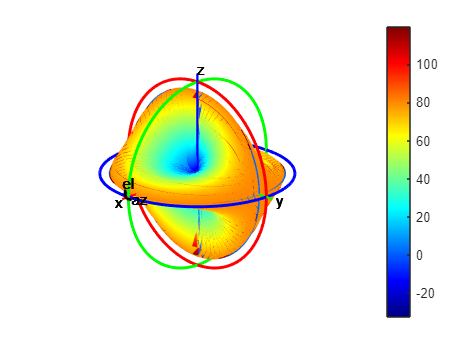

C0 = 41.2;
C1 = 29.7245;
C2 = 9.6243;

d = 0.0939;
lambda0 = 0.142;
theta = linspace(-90,90,37);
phi = linspace(-180,180,73); 

d = 0.0939; 
u = zeros(73,37);
for i=1:73
    for j=1:37
u(i,j) = (pi*d/lambda0)*cos(deg2rad(phi(i)))*sin(deg2rad(theta(j)));
% g = gain(fc,[30;20])
    end
end

ArF = zeros(73,37);
for i=1:73
    for j=1:37
ArF(i,j) = C0*cos(u(i,j))+C1*cos(3*u(i,j))+C2*cos(5*u(i,j));
    end
end
Gain_factor = ArF.^2/(C0^2+2*C1^2+2*C2^2);
patternCustom(ArF,90-theta,phi);

## NEAR FIELD 

L_max = 5*W+4*0.0939; 
LL = linspace(0,L_max,1);
[X,Y]=meshgrid(LL,LL); 
fre=0.68*sqrt((L_max)^3/lambda0);
pfre=[X(:)';Y(:)';(fre/2)*ones(1,prod(size(X)))];




figure;
EHfields(tcheB,f,[1; 1; 1])

Check for incorrect argument data type or missing argument in call to function 'EHfields'.